# dVRK PSM (Matlab Robotics Toolbox)

% clear,close all;
dhparams = [0   pi/2	0   pi/2;
            0   -pi/2   0   -pi/2;
            0   pi/2    -0.4318 0;
            0   	0	0.4162	0;
            0       -pi/2	0   	-pi/2;
            0.0091       -pi/2       0       -pi/2];


PSM_MRT = rigidBodyTree;

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','prismatic');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');
body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5','revolute');
body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6','revolute');

setFixedTransform(jnt1,dhparams(1,:),'mdh');
setFixedTransform(jnt2,dhparams(2,:),'mdh');
setFixedTransform(jnt3,dhparams(3,:),'mdh');
setFixedTransform(jnt4,dhparams(4,:),'mdh');
setFixedTransform(jnt5,dhparams(5,:),'mdh');
setFixedTransform(jnt6,dhparams(6,:),'mdh');

body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;
body5.Joint = jnt5;
body6.Joint = jnt6;

addBody(PSM_MRT,body1,'base')
addBody(PSM_MRT,body2,'body1')
addBody(PSM_MRT,body3,'body2')
addBody(PSM_MRT,body4,'body3')
addBody(PSM_MRT,body5,'body4')
addBody(PSM_MRT,body6,'body5')
showdetails(PSM_MRT)

--------------------
Robot: (6 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3    prismatic            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5     revolute            body4(4)   body6(6)  
   6        body6         jnt6     revolute            body5(5)   
--------------------


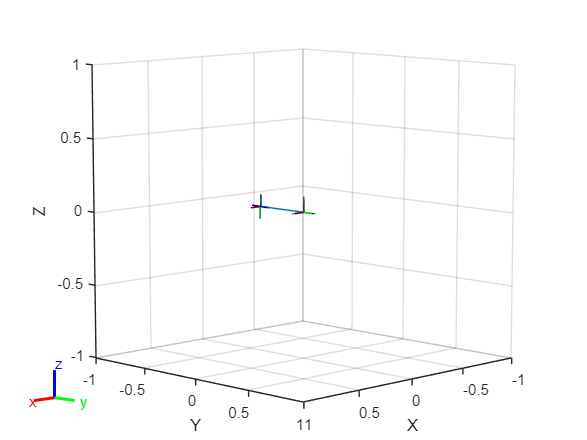


show(PSM_MRT);

config1 = randomConfiguration(PSM_MRT)

config1 = 1×6 struct array with fields:
    JointName
    JointPosition


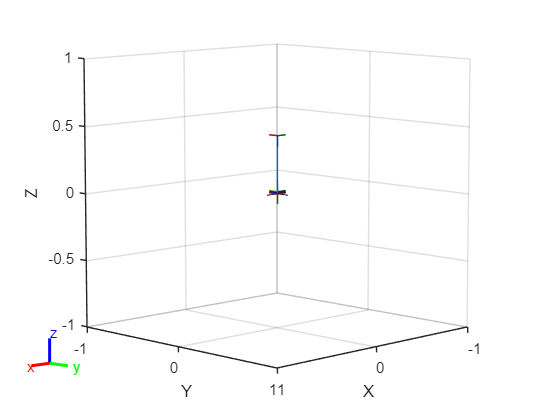

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


config1(1).JointPosition = 0+pi/2;
config1(2).JointPosition = 0-pi/2;
config1(3).JointPosition = 0-0.4318;
config1(4).JointPosition = 0;
config1(5).JointPosition = 0-pi/2;
config1(6).JointPosition = 0-pi/2;

show(PSM_MRT, config1)


getTransform(PSM_MRT,config1,'body6')

ans =    -1.0000         0    0.0000    0.0000
   -0.0000   -0.0000   -1.0000    0.0000
   -0.0000   -1.0000    0.0000    0.0065
         0         0         0    1.0000


ik = inverseKinematics('RigidBodyTree',PSM_MRT)

ik =   inverseKinematics with properties:

       RigidBodyTree: [1×1 rigidBodyTree]
     SolverAlgorithm: 'BFGSGradientProjection'
    SolverParameters: [1×1 struct]


rng(4);
lowerBound = [-pi/2, -pi/3, 0, -pi*17/18, -pi*17/18, -pi*17/18];
upperBound = [pi/2, pi/3, 1, pi*17/18, pi*17/18, pi*17/18];
totalSuccess = 0;
totalCorrection = 0;
config1 = randomConfiguration(PSM_MRT)

config1 = 1×6 struct array with fields:
    JointName
    JointPosition



tic
for i=1:100
    realQ = (upperBound - lowerBound).*rand(1,6) + lowerBound;
    transMat = PSM.fkine(realQ).T;
    weights = [1,1,1,1,1,1];
    configSol = ik('body6',transMat,weights,config1);

end
toc

Elapsed time is 22.763521 seconds.


% Geometric Jacobian
J0 = geometricJacobian(PSM_MRT, config1,'body6')

J0 =     0.0000   -1.0000         0   -0.0000   -1.0000    0.0000
   -1.0000   -0.0000         0   -0.0000   -0.0000   -1.0000
    0.0000    0.0000         0   -1.0000    0.0000    0.0000
   -0.0065   -0.0000   -0.0000   -0.0000    0.0000         0
    0.0000    0.0065   -0.0000   -0.0000   -0.0091         0
    0.0000   -0.0000   -1.0000    0.0000    0.0000         0


$$theta\_dot\_1 = {\dot{\theta }}_{1}$$